# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.- Operating table. It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Use 'patch' or 'fill3' functions to model it.

*Add your comemnts here..... be concise*

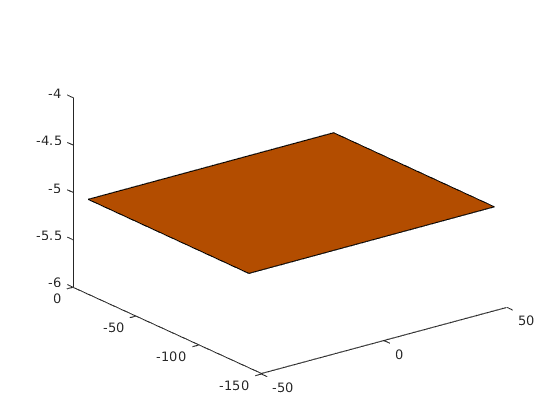

clc
clear

X_table = [50 -50 -50 50];
Y_table = [-140 -140 -12 -12];
Z_table = [-5 -5 -5 -5];

X=[1,0 0];
Y=[0,1,0];
Z=[0,0,1];

h2=fill3(X_table,Y_table,Z_table,[0.7 0.3 0]);

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

%Options
skin1 = [0.9290 0.6940 0.1250];
skin2 =  [1 0.4 0.6];

[V,F,UV,TF,Ndicom,NF] = readOBJ('Human_body.obj');

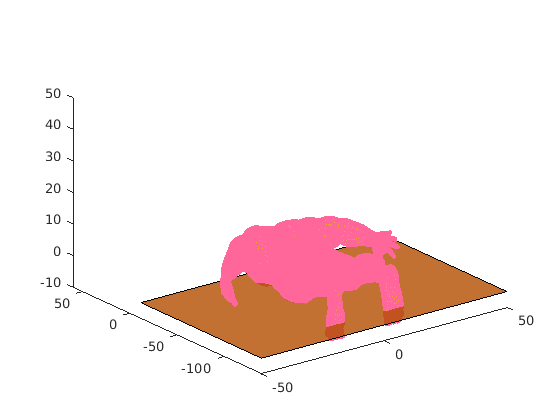


%Resize, translate and Display
V = V*6;

T= transl(0,-40,0);

theta=pi;
Ry=roty(theta);

V=V*Ry;

for i=1:size(V,1)
    for j=1:size(V,2)
            aux = [V(i,:) 1]';
            P = T*aux;
            V(i,:) = P(1:3);
    end
end

%Axis
ylim([-140 60]);
xlim([-50 50]);
zlim([-10 50]);

p = patch('faces',F,'vertices',V,'FaceColor',skin1,'EdgeColor',skin2);
alpha(0.8)

3.- A human skull model, embedded in the head of the human. Place the fiducials.

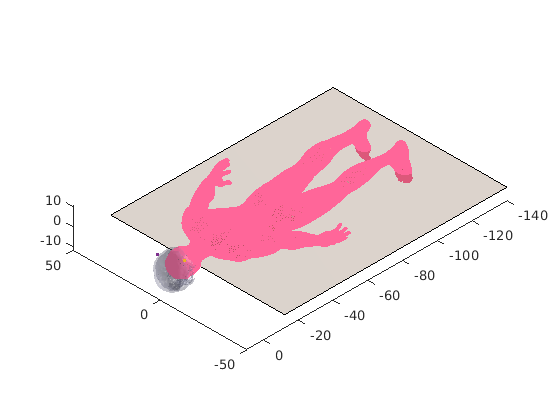

%Variables
global dis_pos_width;
global dis_neg_width;
global dis_pos_depth;
global dis_neg_depth;
global dis_pos_height;
global dis_neg_height;

global dic_pos_width;
global dic_neg_width;
global dic_pos_depth;
global dic_neg_depth;
global dic_pos_height;
global dic_neg_height;

skull_color_2=[0 0 0.7];
skull_color_1=[1 1 1];
skul_height=3;
Ndicom=112;
height_img= round(skul_height/Ndicom,2);

%% Load
fv = stlread('Crani.stl');

%% Ficudals coordinates
% Skull is centered on (0,0,0)
% Display coordinates: Set by Skull's container box (mm)

dis_pos_width = max(fv.vertices(:,1));
dis_neg_width = min(fv.vertices(:,1));

dis_pos_depth = max(fv.vertices(:,2));
dis_neg_depth = min(fv.vertices(:,2));

dis_pos_height = max(fv.vertices(:,3));
dis_neg_height = min(fv.vertices(:,3));

%Dicom coordinates: Get Skull's container box in dicom images (mm)
%Obtained from slice 62, the biggest size.

dic_pos_width = 204;
dic_neg_width = 42;

dic_pos_depth = 234;
dic_neg_depth = 26;

dic_pos_height = Ndicom;
dic_neg_height = 1;


%ficudals x,y in dicom coordinates. Get from images.
%ficudal z, in dicom coord, corresponds with num of slice

dicom_fic_1 = [121,210,19];
dicom_fic_2 = [183,210,48];
dicom_fic_3 = [70,210,81];

%Convert ficudals dicom coordinates to display coord

display_fic_1=[X_dicom2display(dicom_fic_1(1)),...
    Y_dicom2display(dicom_fic_1(2)),...
    Z_dicom2display(dicom_fic_1(3))];

display_fic_2=[X_dicom2display(dicom_fic_2(1)),...
    Y_dicom2display(dicom_fic_2(2)),...
    Z_dicom2display(dicom_fic_2(3))];

display_fic_3=[X_dicom2display(dicom_fic_3(1)),...
    Y_dicom2display(dicom_fic_3(2)),...
    Z_dicom2display(dicom_fic_3(3))];

%% Transforms
% Resize
fv.vertices = fv.vertices*0.1;
display_fic_1 = display_fic_1*0.1;
display_fic_2 = display_fic_2*0.1;
display_fic_3 = display_fic_3*0.1;

%Rotate
theta=pi/2;
Rx=rotx(theta);
fv.vertices = fv.vertices*Rx;
display_fic_1 = display_fic_1*Rx;
display_fic_2 = display_fic_2*Rx;
display_fic_3 = display_fic_3*Rx;

theta=pi;
Ry=roty(theta);
fv.vertices = fv.vertices*Ry;
display_fic_1 = display_fic_1*Ry;
display_fic_2 = display_fic_2*Ry;
display_fic_3 = display_fic_3*Ry;

%% Display
% Fix the axes scaling, and set a nice view angle

hold on
plot3(display_fic_1(1),display_fic_1(2),display_fic_1(3),'.');
hold on
plot3(display_fic_2(1),display_fic_2(2),display_fic_2(3),'.');
hold on
plot3(display_fic_3(1),display_fic_3(2),display_fic_3(3),'.');
hold on;
printSkull;

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

%Variables

global xmin;
global xmax;
global ymin;
global ymax;

%Left is ymin and top is xmin
xmin = 70;
xmax = 120;
ymin = 105;
ymax = 155;
NSlides = 112;

%% Load
[VV,ss,dd] = dicomreadVolume(fullfile('./Skull_Tumor/Skull_Tumor/')); 
VV = squeeze(VV);
VV = VV*0.1;

%Begins from 112 not from 1
%Work with two first in order to align
tumor_begin_slice = NSlides-40;
tumor_end_slice = NSlides-20;

%Color
colormap 'Bone';
tumor_slices = tumor_begin_slice:tumor_end_slice;

%% Keep only Tumor 
for k=1:size(VV,3)
    for i=1:size(VV,1)
        for j=1:size(VV,2)
            if(isTumor(i,j) == 0)
                VV(i,j,k)=0;
            end
        end
    end
end

%% Move Tumor display

xn = (-135:120)*0.1;
yn = (-150:105)*0.1;
zn = (1:112)*0.1;

xn = xn';
yn = yn';
zn = zn';

hold on

contourslice(xn,yn,zn,VV,[],[],tumor_slices,2);


*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

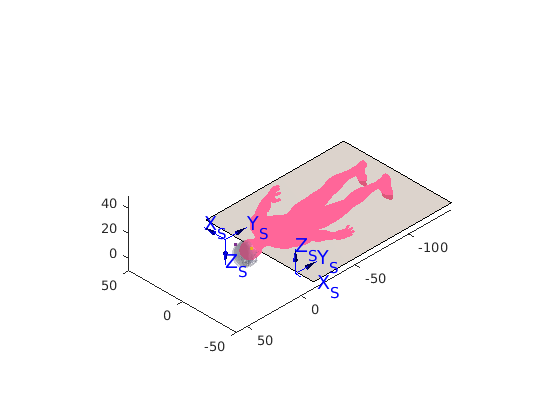

%Axis
ylim([-140 60]);
xlim([-50 50]);
zlim([-10 50]);

%Table
hold on
table=transl(-45,0,5)*trotz(pi)*eye(4);
trplot(table, 'frame','S','length',10,'text_opts', {'FontSize', 14},'arrow','color', 'b','thick',1);

%Skull
hold on
theta=-theta;
skull=transl(0,20,20)*trotx(theta)*eye(4);
trplot(skull, 'frame','S','length',10,'text_opts', {'FontSize', 14},'arrow','color', 'b','thick',1);

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*Add your comemnts here.....be concise*

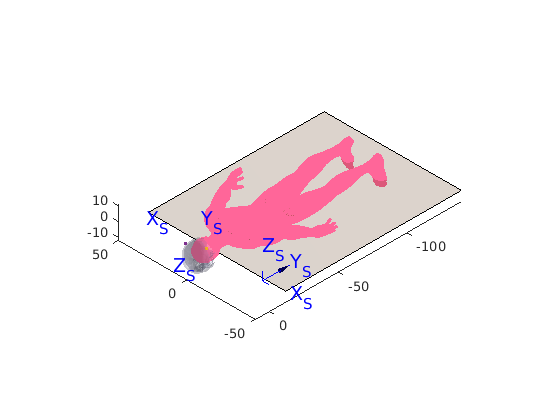

hold on

run mdl_puma560_Craigh

Error using run (line 66)
mdl_puma560_Craigh not found.


%p560Craigh.tool = SE3(0, 0, 0.2);
p560Craigh.base = SE3(-5, 20, 2);

%Plot
p560Craigh.plot(qz);


7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

9.- Prepare a script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

%% put your code Here

10.- Prepare a script that perform trepanation.

*Add your comemnts here.....be concise*

%% put your code Here

11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

%% put your code Here

*Second approach:**  Assume that the ZX plane of the Robot is not aligned with plane of symetry of the human body and it is needed a orientation calibration.*

12.-Get the transformation that maps tumor points in Robot Frame. See teacher help: Triangle.mlx

*Add your comemnts here.....be concise*

%% put your code Here

13.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

14.-Use the script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

%% put your code Here

15.- Use the  script that perform trepanation.

*Add your comemnts here.....be concise*

%% put your code Here

16.- Use the script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

%% put your code Here

## Functions

function X = X_dicom2display(xdicom)
    
    global dis_pos_width;
    global dis_neg_width;
    global dic_pos_width;
    global dic_neg_width;
    
    a = (xdicom-dic_neg_width);
    b = (dic_pos_width-dic_neg_width);
    c = -(dis_neg_width);
    d = (dis_pos_width-dis_neg_width);
    
    Xdec = ((a*d)-(b*c))/(b);    
    X = round(Xdec);

end

function Y = Y_dicom2display(ydicom)

    global dis_pos_depth;
    global dis_neg_depth;
    global dic_pos_depth;
    global dic_neg_depth;
    
    a = (ydicom-dic_neg_depth);
    b = (dic_pos_depth-dic_neg_depth);
    c = -(dis_neg_depth);
    d = (dis_pos_depth-dis_neg_depth);
    
    Ydec = ((a*d)-(b*c))/(b);
    Y = round(Ydec);

end

function Z = Z_dicom2display(zdicom)

    global dis_pos_height;
    global dis_neg_height;
    global dic_pos_height;
    global dic_neg_height;
    
    a = (zdicom-dic_neg_height);
    b = (dic_pos_height-dic_neg_height);
    c = -(dis_neg_height);
    d = (dis_pos_height-dis_neg_height);
    
    Zdec = ((a*d)-(b*c))/(b);    
    Z = round(Zdec);

end


function ret=isTumor(i,j)

    global xmin;
    global xmax;
    global ymin;
    global ymax;

    ret = 0;

    if((i>xmin)&&(i<xmax)&&(j>ymin)&&(j<ymax))
        ret = 1;
    end
   
end